Michal Szabo

12.1.2022

# Final Assignment

## Displaying our data

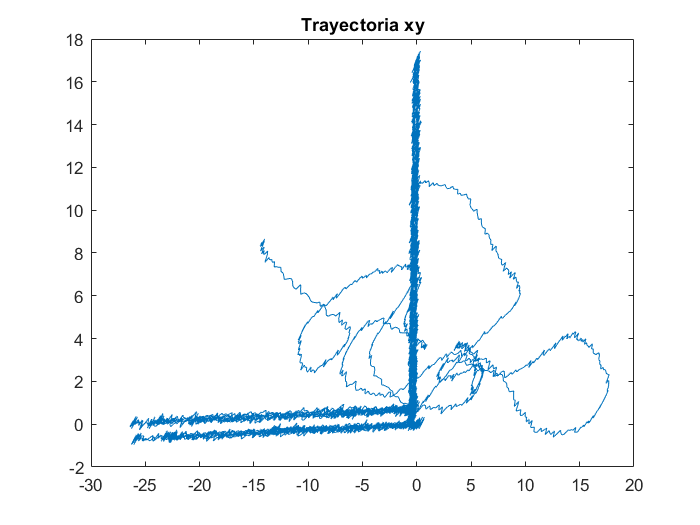

close all; clear
data = importdata('exp_ini_fase1.txt');
dibujaEnsayo(data)

% Data explanation
t=data(:,1);   % Time
T = t(4)-t(3); % Time step
x=data(:,2);   % Position x [m]
vx=data(:,3);  % Velocity x [m/s]
y=data(:,4);   % Position y [m]
vy=data(:,5);  % Velocity y [m/s]
mp=data(:,6);  % Pitch reference
mr=data(:,7);  % Roll reference

## 1. Data division

set1 = data(2751:5401,:);    % (165s - 324s)
set2 = data(8068:10734,:);   % (484.02s - 643.98s)
set3 = data(10735:end,:);    % (644.04s - 720s)

% Identification data
y_i=set1(:,4);    % Position y [m]
vy_i=set1(:,5);   % Velocity y [m/s]
mr_i=set1(:,7);   % Roll reference

% Validation data
y_v=set2(:,4);    % Position y [m]
vy_v=set2(:,5);   % Velocity y [m/s]
mr_v=set2(:,7);   % Roll reference

% Final comparison data
y_fc=set3(:,4);   % Position y [m]
vy_fc=set3(:,5);  % Velocity y [m/s]
mr_fc=set3(:,7);  % Roll reference

## 2. Estimating delay

Estimation of the delay can be done manually by looking at the graph of roll reference and velocity on y direction. The delay is how long does it take for velocity to act on the reference change, divided by the time sample. 

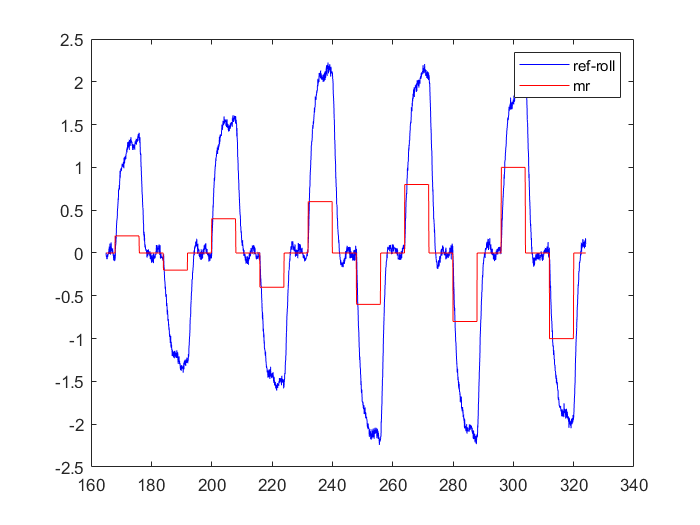

figure
plot(set1(:,1),vy_i,'blue'),hold on
plot(set1(:,1),mr_i,'red'),hold off
legend('ref-roll','mr')

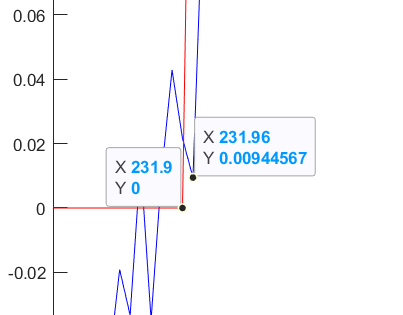

And with calculation of difference in time (X) and dividing that by the time step we can find our delay.

nk = (231.96-231.9)/T  % manually

nk = 1.0000

Calculating it with MATLAB function

id = iddata(vy,mr,T); % we need to define our iddata
nk = delayest(id) 

nk = 1

## 3. Linear ARX model

To find the order of the polynomial the order estimation in Identification Toolbox was used. Since the objective is the model that can fit the data the best way the red option was chosen with the highest order of 10 for a and b parameters with the delay of 1 which we calculated. With increasing order there were only small changes in Misfit, thats why the default option of maximum order of 10 was used in order to prevent overfitting.

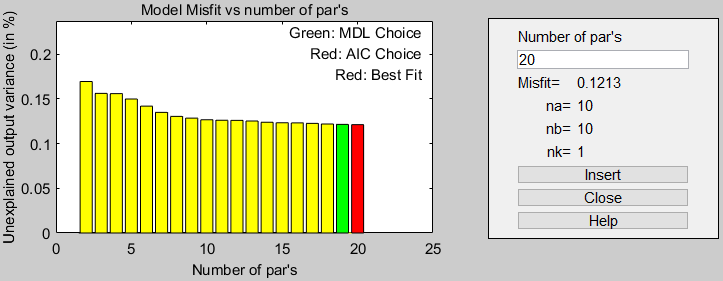

This model was able to predict the velocity with 69.32% accuracy.

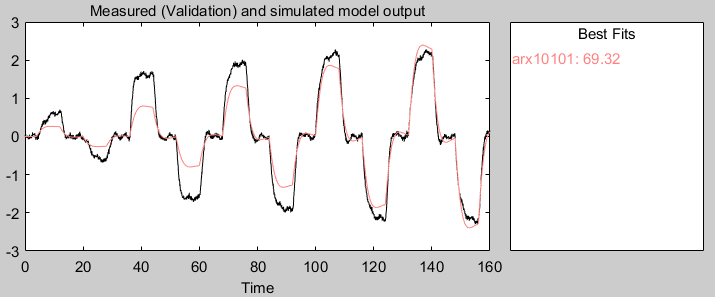

## 4. Hammerstein-Wiener model

For this model the search estimation was set to automatic with maximum of 20 iterations as default. The input breakpoints were chosen by studying the graph of the input.

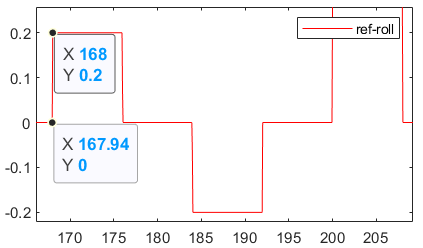

The decided value for input breakpoints was 2, because of the square input signal which has 2 breakpoints as shown on the figure. For the output, the 3 breakpoints were found to work best with trial and error. The second best was with 10 breakpoints. The displayed prediction of the models is on the following figure.

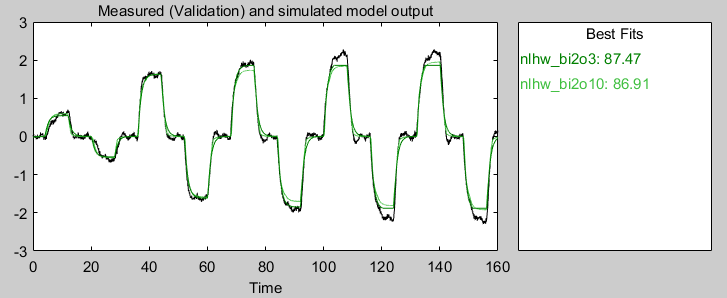

Model with 2 input and 3 output breakpoints has an accuracy of 87.47%. The model with 2 input and 10 output vectors has an accuracy of 86.91%. These were the best models found. With increasing number of input breakpoints the accuracy was decreasing so the estimation of 2 input breakpoints was correct.

## 5. Non-linear ARX model with multiple regressors

For the exercise, the non-linear ARX with multiple regressors was chosen as it has the best results. The models that were created were with one linear regressor, with linear and polynomial regressor and with one linear and two polynomial regressors. The option of taking only a polynomial regressor did not work for this data and also different combinations of regressors were not that effective. There was also an option of including the mixed variables when estimating the model which helped getting better results for one of the models. All the models we designed are desplayed in the following figure.

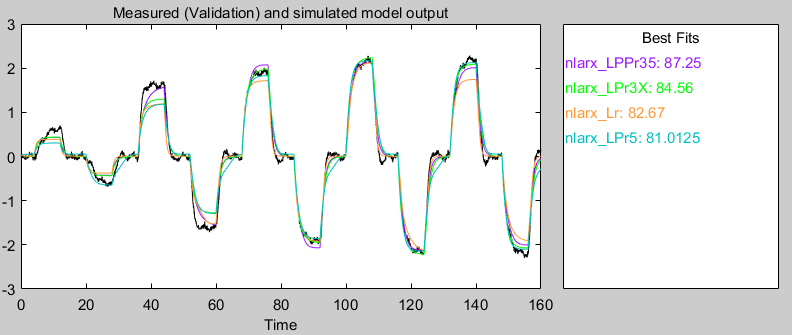

The best model was the one with one linear and two polynomial regressors in this order. The first polynomial is the order of 3 and the second the order of 5. This model accuracy on our validation data set was 87.25%. Another model has one linear and polynomial regressor with order of 3, but now with the option of including mixed parameters. Acuuracy of this model was 84.56%. Another model was estimated with only a linear regressor and has accuracy of 82.67%. The fourth model was estimated with one linear and one polynomial regressor with 5th order and accuracy of 81.01%.

## 6. Final comparison on dataset 3

First we compare all the models on the validation data.

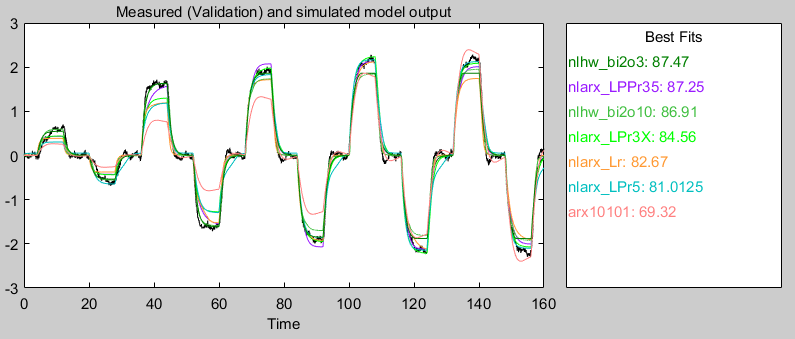

As we can see, the model with the highest fit is the Hammerstein-Wiener model, but when looking at another figure, we can see that Hammerstein-Wiener models have high autocorrelation of residuals which means that the model is misspecified, that some variables are missing in the model. Where the ARX models are close to zero which is good.

 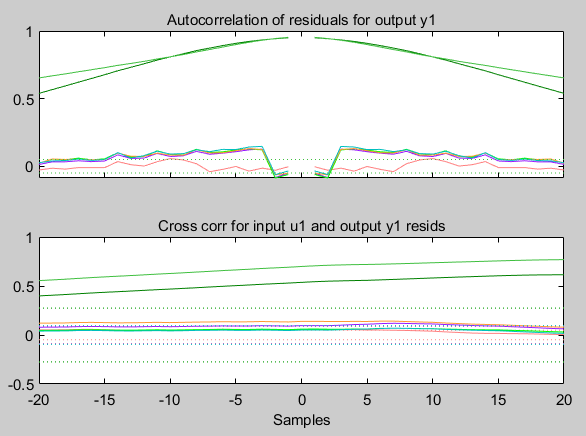

For final comparison we used our models on dataset 3. The estimations of the models are displayed on the following figure.

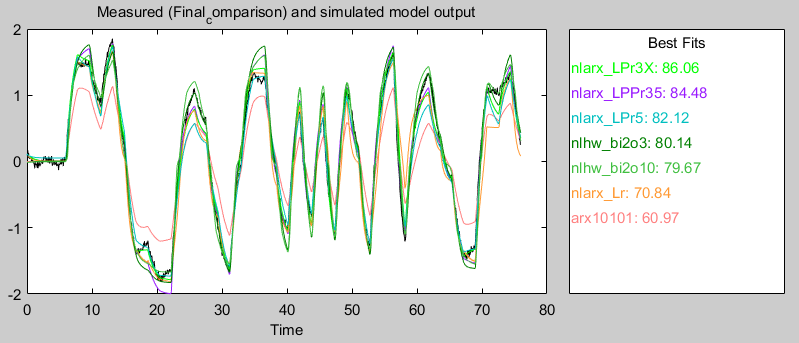

The best results with 86.06% fit, were obtained by using a non-linear ARX model with one linear and one polynomial regressor with 3rd order and with included mixed parameters. It's interesting that some of these non-linear ARX models have better fit on these random burst data than on the validation data which are quite simmilar to identification data. Next figure shows the correlation of residuals for this particular data.

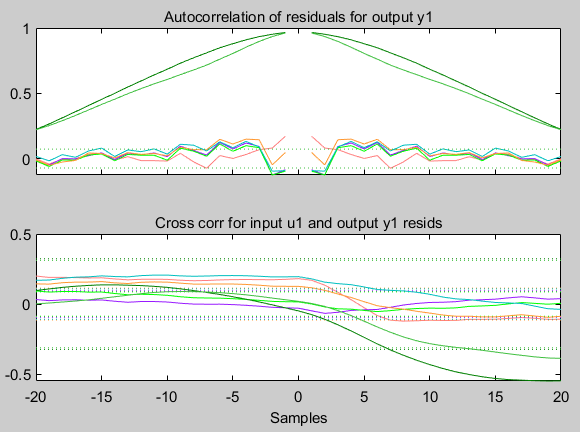

I have chosen the non-linear ARX model with one linear and one polynomial regressor with 3rd order and included mixed variables because it is most accurate when fitting the data. It also has one of the lowest autocorrelation of residuals and also the Cross correlation between the input and output is very close to zero.

This model can be useful for better control of the drone because it can quite accurately calculate what will be the drone speed and position with some input. This way we will be better with manoovering the drone and we could probably create a self driving drone.

## 7. Conclusions

I have understood what parameters are important and how to create a better prediction model based on regression. Models strictly depend on the data we feed them and which parameters do we obtain from them. It is very important to choose the right order of the system in order to get a accurate estimation but not just for the validation data, but any data which could represent a normal behaviour of the drone. The delay of the reaction to input is also quite important for better precision when calculating the parameters. The more regressors the non-linear ARX model has, does not necessary mean that its going to be better as we can see from the results.  

## Table (necessary to export the models from Identification Toolbox GUI)

aic(nlhw_bi2o3)

Unrecognized function or variable 'nlhw_bi2o3'.

aic(nlhw_bi2o10)
aic(arx10101)
aic(nlarx_Lr)
aic(nlarx_LPr5)
aic(nlarx_LPr3X)
aic(nlarx_LPPr35)

fpe(nlhw_bi2o10)
nlhw([vy_i,mr_i],nlhw_bi2o10)
fpe(nlhw_bi2o3)
nlhw([vy_i,mr_i],nlhw_bi2o3)